clear
r = 625+1000;
L = 750;
theta = L/1000

theta = 0.7500

rad2deg(theta)

ans = 42.9718

th = -theta/2:theta/6:theta/2

th =    -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750


v = 1500; 
T = L/v; %(s) Cycle Time
B = 0.5;
Tt = (1-B)*T; %Transfer Time
Ts = B*T; % Support Time
dt = Tt/6

dt = 0.0417





x  = r*cos(th)

x = 	1.0e+03 *

    1.5121    1.5745    1.6123    1.6250    1.6123    1.5745    1.5121


y  = r*sin(th)

y =  -595.1929 -402.0314 -202.5964         0  202.5964  402.0314  595.1929


z_dot_max = 6;
z_ddot_max = z_dot_max/dt

z_ddot_max = 144



%Z-direction:
z_ddot_fg_pts = [z_ddot_max -z_ddot_max 0 0 -z_ddot_max z_ddot_max 0];
z_dot_fg_pts = zeros(1,7);

for i = 1:6
    z_dot_fg_pts(i+1) = z_dot_fg_pts(i) + z_ddot_fg_pts(i)*dt ;
end
z_dot_fg_pts

z_dot_fg_pts =      0     6     0     0     0    -6     0



%Vertical Movement of the foot with respect to ground (z_fg):
z_fg_pts = zeros(1,7);
zs_fg_pts = zeros(1,7);

for i = 1:6
    z_fg_pts(i+1) = z_fg_pts(i) + z_dot_fg_pts(i)*dt + (1/2)*z_ddot_fg_pts(i)*dt^2;
end
z=z_fg_pts*1000

z =      0   125   250   250   250   125     0


xd  = -v*sin(th)

xd =   549.4088  371.1059  187.0121         0 -187.0121 -371.1059 -549.4088


yd  = v*cos(th)

yd = 	1.0e+03 *

    1.3958    1.4534    1.4883    1.5000    1.4883    1.4534    1.3958


xd(1)= 0

xd =          0  371.1059  187.0121         0 -187.0121 -371.1059 -549.4088


xd(end)=0

xd =          0  371.1059  187.0121         0 -187.0121 -371.1059         0


yd(1)= 0

yd = 	1.0e+03 *

         0    1.4534    1.4883    1.5000    1.4883    1.4534    1.3958


yd(end)=0

yd = 	1.0e+03 *

         0    1.4534    1.4883    1.5000    1.4883    1.4534         0


tpts = 0:dt:Ts

tpts =          0    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500


tvec = linspace(0,Ts,200)

tvec =          0    0.0013    0.0025    0.0038    0.0050    0.0063    0.0075    0.0088    0.0101    0.0113    0.0126    0.0138    0.0151    0.0163    0.0176    0.0188    0.0201    0.0214    0.0226    0.0239    0.0251    0.0264    0.0276    0.0289    0.0302    0.0314    0.0327    0.0339    0.0352    0.0364    0.0377    0.0389    0.0402    0.0415    0.0427    0.0440    0.0452    0.0465    0.0477    0.0490    0.0503    0.0515    0.0528    0.0540    0.0553    0.0565    0.0578    0.0590    0.0603    0.0616


[q, qd, qdd, pp] = cubicpolytraj([x;y;z], tpts, tvec,"VelocityBoundaryCondition",[xd;yd;z_dot_fg_pts])

q = 	1.0e+03 *

    1.5121    1.5122    1.5127    1.5134    1.5144    1.5156    1.5170    1.5187    1.5205    1.5225    1.5247    1.5270    1.5294    1.5319    1.5345    1.5371    1.5398    1.5425    1.5452    1.5479    1.5506    1.5532    1.5557    1.5582    1.5606    1.5628    1.5649    1.5669    1.5687    1.5703    1.5717    1.5728    1.5738    1.5744    1.5749    1.5756    1.5763    1.5772    1.5782    1.5792    1.5804    1.5816    1.5829    1.5843    1.5857    1.5871    1.5886    1.5901    1.5917    1.5932
   -0.5952   -0.5947   -0.5934   -0.5912   -0.5882   -0.5845   -0.5801   -0.5751   -0.5696   -0.5635   -0.5569   -0.5500   -0.5427   -0.5351   -0.5272   -0.5192   -0.5110   -0.5027   -0.4944   -0.4861   -0.4779   -0.4698   -0.4619   -0.4543   -0.4469   -0.4399   -0.4332   -0.4270   -0.4214   -0.4162   -0.4117   -0.4079   -0.4047   -0.4023   -0.4003   -0.3975   -0.3940   -0.3899   -0.3852   -0.3800   -0.3743   -0.3682   -0.3617   -0.3548   -0.3476   -0.3401   -0.3324   -0.3246   

qd = 	1.0e+03 *

         0    0.2414    0.4685    0.6813    0.8798    1.0640    1.2338    1.3893    1.5305    1.6574    1.7700    1.8683    1.9523    2.0219    2.0772    2.1182    2.1449    2.1573    2.1554    2.1391    2.1086    2.0637    2.0045    1.9310    1.8432    1.7410    1.6246    1.4938    1.3487    1.1893    1.0156    0.8276    0.6253    0.4086    0.4589    0.5580    0.6503    0.7356    0.8142    0.8858    0.9506    1.0085    1.0596    1.1038    1.1411    1.1716    1.1952    1.2120    1.2219    1.2249
         0    0.7297    1.4167    2.0611    2.6629    3.2220    3.7385    4.2123    4.6435    5.0320    5.3779    5.6811    5.9417    6.1597    6.3350    6.4676    6.5577    6.6050    6.6098    6.5718    6.4913    6.3681    6.2022    5.9937    5.7426    5.4488    5.1124    4.7333    4.3116    3.8472    3.3402    2.7906    2.1983    1.5633    1.9415    2.4942    3.0106    3.4909    3.9351    4.3430    4.7148    5.0504    5.3499    5.6132    5.8403    6.0312    6.1860    6.3046  

qdd = 	1.0e+05 *

    1.9787    1.8647    1.7508    1.6368    1.5229    1.4089    1.2950    1.1811    1.0671    0.9532    0.8392    0.7253    0.6113    0.4974    0.3834    0.2695    0.1555    0.0416   -0.0724   -0.1863   -0.3003   -0.4142   -0.5281   -0.6421   -0.7560   -0.8700   -0.9839   -1.0979   -1.2118   -1.3258   -1.4397   -1.5537   -1.6676   -1.7816    0.8162    0.7615    0.7069    0.6523    0.5977    0.5430    0.4884    0.4338    0.3792    0.3245    0.2699    0.2153    0.1607    0.1060    0.0514   -0.0032
    5.9780    5.6386    5.2991    4.9597    4.6202    4.2808    3.9413    3.6019    3.2624    2.9230    2.5835    2.2441    1.9046    1.5652    1.2257    0.8863    0.5468    0.2074   -0.1321   -0.4715   -0.8110   -1.1504   -1.4899   -1.8293   -2.1688   -2.5082   -2.8477   -3.1871   -3.5266   -3.8660   -4.2055   -4.5449   -4.8844   -5.2238    4.5429    4.2550    3.9671    3.6792    3.3913    3.1034    2.8155    2.5276    2.2397    1.9518    1.6639    1.3759    1.0880    0.8001 

pp = struct with fields:
      form: 'pp'
    breaks: [-1 0 0.0417 0.0833 0.1250 0.1667 0.2083 0.2500 1.2500]
     coefs: [24×4 double]
    pieces: 8
     order: 4
       dim: 3



plot3(q(1,:),q(2,:), q(3,:),x,y,z,'or')
axis equal
% z
% z = dt*6*ones(1,length(x))
% z(1) = 0;
% z(end)=0;
% z

% xx = zeros(1,length(x)+2)
% yy = zeros(1,length(x)+2)
% zz = zeros(1,length(x)+2)
% 
% xx(1)=x(1)
% xx(2:6)=x
% xx(end)=x(end)
% 
% yy(1)=y(1)
% yy(2:6)=y
% yy(end)=y(end)
% 
% 
% zz(2:6)=z
plot3(x,y,z_fg_pts)


plot(x,y)
axis equal
plot(x)
plot(y)
plot(z_fg_pts)

xd  = -v*sin(th)

xd =   549.4088  371.1059  187.0121         0 -187.0121 -371.1059 -549.4088


yd  = v*cos(th)

yd = 	1.0e+03 *

    1.3958    1.4534    1.4883    1.5000    1.4883    1.4534    1.3958



plot(xd,yd)
plot(xd)
plot(yd)

xdd  = -r*cosd(theta)

xdd = -1.6249e+03

ydd  = -r*sind(theta)

ydd = -21.2706

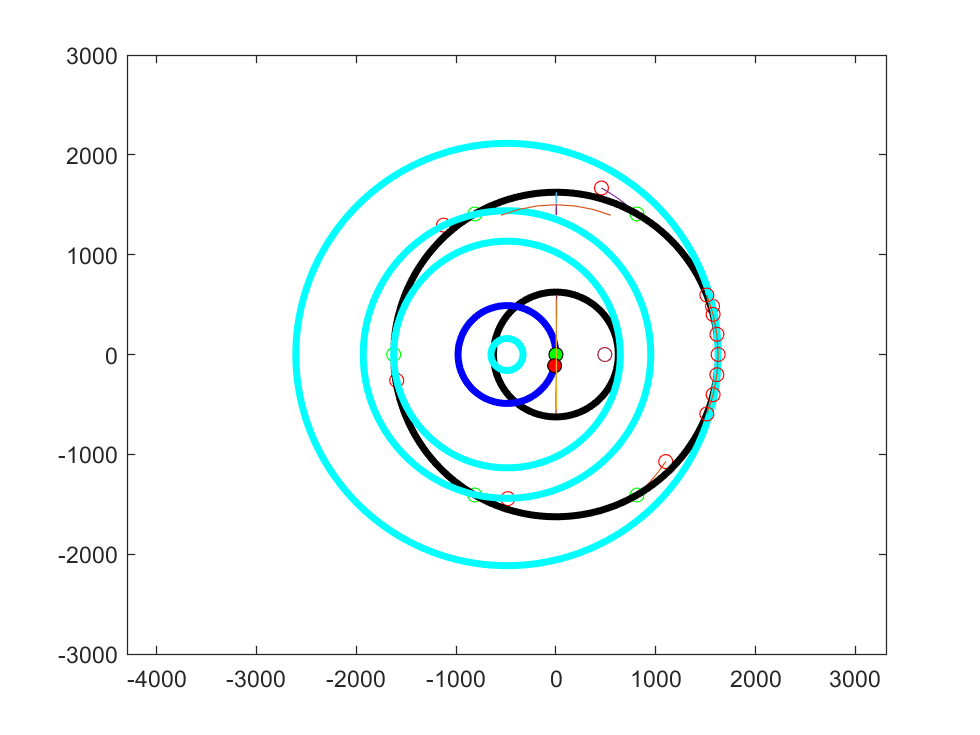


plot(xdd,ydd)
plot(xdd)
plot(ydd)


sind(theta)

ans = 0.0131



theta_s = deg2rad(15)

theta_s = 0.2618



%%%%%%
beta = deg2rad(60)

beta = 1.0472

s1 = [r*cos(2*beta), r*sin(2*beta), 0]';
s2 = [r*cos(1*beta), r*sin(1*beta), 0]';
s3 = [r*cos(3*beta), r*sin(3*beta), 0]';
s4 = [r*cos(0*beta), r*sin(0*beta), 0]';
s5 = [r*cos(4*beta), r*sin(4*beta), 0]';
s6 = [r*cos(5*beta), r*sin(5*beta), 0]';
figure()
s = [s1, s2, s3, s4, s5, s6];
t = linspace(0,Ts,50);

R = 979.9221; % turn radius
ss = -1; % forward (+1)/reverse (-1)
d= 1; % left (+1)/right (-1)
theta_max = (L)/(R+r)

theta_max = 0.2879

theta_b =L/2/R

theta_b = 0.3827


% w = ss*d*theta_max/Ts
w= ss*d*theta_b/Ts

w = -1.5307

wb= ss*d*theta_b/Ts

wb = -1.5307

w_robot = (L/2)/r/Ts

w_robot = 0.9231

if abs(wb) >= w_robot
    wb = ss*d*w_robot
    w = ss*d*w_robot
end

wb = -0.9231

w = -0.9231


l = w*Ts*r

l = -375

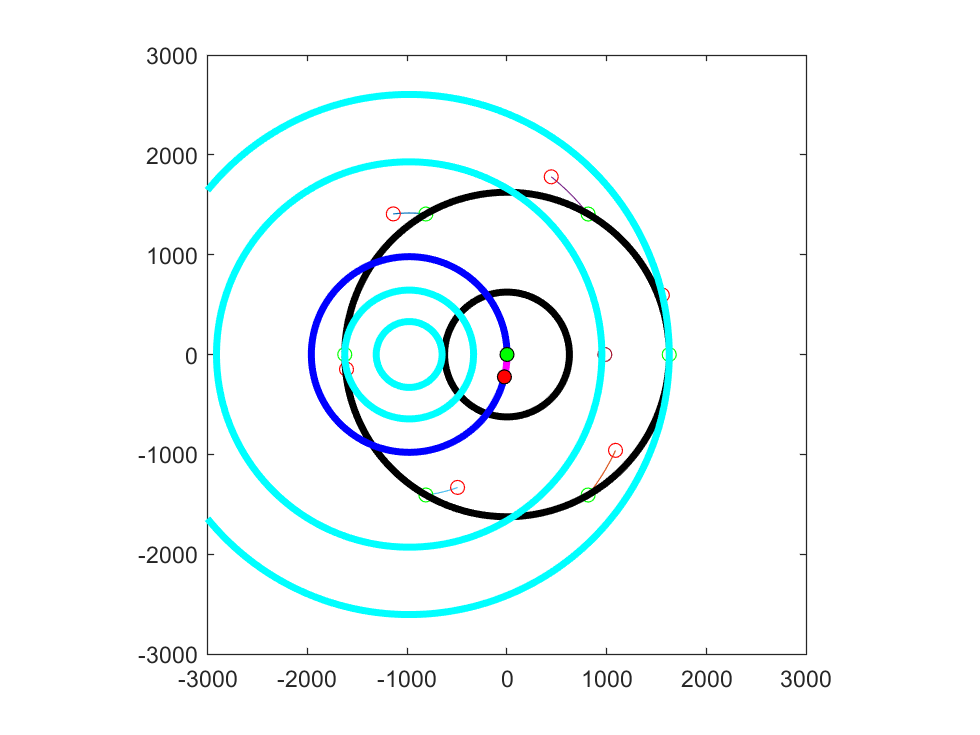

Xb = -R*(1-cos(wb.*t))*d;
Yb = R.*sin(wb.*t)*d;

for i = 1:length(s)
xA = s(1,i);
yA = s(2,i);

% w = theta/Ts


% R = 5000;
% ss = -1; % forward (+1)/reverse (-1)
% d= -1; % left (+1)/right (-1)
% theta_max = (L)/(R+r);
% theta_b =L/2/R;
% 
% w = ss*d*theta_max/Ts
% wb= ss*d*theta_b/Ts
% 
% Xb = R*(1-cos(wb.*t))*-d;
% Yb = R.*sin(wb.*t)*d;

Tx = R*(1-cos(w.*t))*d;
Ty = R.*sin(w.*t)*d;
% X = xA.*cos(w.*t)+yA.*sin(w.*t)-R*(1-cos(w.*t))
% Y = -xA.*sin(w.*t)+yA.*cos(w.*t)-R.*sin(w.*t)
i;
X = xA.*cos(w.*t)+yA.*sin(w.*t)-Tx;
Y = -xA.*sin(w.*t)+yA.*cos(w.*t)-Ty;
Z = zeros(1,length(X));


% Xb = R*(1-cos(wb.*t))*-d;
% Yb = R.*sin(wb.*t)*d;
% RRR=Rotz(deg2rad(120))*[X;Y;Z]
% X =RRR(1,:)
% Y = RRR(2,:)
% figure()
plot(X,Y)
hold on
% scatter([xA, X(end)],[yA, Y(end)] )


scatter(xA, yA,'g' )
scatter(X(end), Y(end),'r' )
axis equal
% plotCircle(1000+625,0,0,0,'k')
% plotCircle(625,0,0,0,'k')
% scatter(R,0)
% plotCircle(R,0,-d*R,0,'b')
% plotCircle(R-650,0,-d*R,0,'c')
% plotCircle(R-1625,0,-d*R,0,'c')
% plotCircle(R+950,0,-d*R,0,'c')
% plotCircle(R+1625,0,-d*R,0,'c')
% plot(Xb,Yb,"LineWidth",3,"Color",'m')
% scatter(Xb(1),Yb(1), 'filled','g', 'MarkerEdgeColor','k')
% scatter(Xb(end),Yb(end),'filled','r','MarkerEdgeColor','k')
xlim([-3000,3000])
ylim([-3000,3000])
end
plotCircle(1000+625,0,0,0,'k')
plotCircle(625,0,0,0,'k')
scatter(R,0)
if (R<1e8) && (R>100)
plotCircle(R,0,-d*R,0,'b')
plotCircle(R-650,0,-d*R,0,'c')
plotCircle(R-1625,0,-d*R,0,'c')
plotCircle(R+950,0,-d*R,0,'c')
plotCircle(R+1625,0,-d*R,0,'c')
end
plot(Xb,Yb,"LineWidth",3,"Color",'m')
scatter(Xb(1),Yb(1), 'filled','g', 'MarkerEdgeColor','k')
scatter(Xb(end),Yb(end),'filled','r','MarkerEdgeColor','k')

function plotCircle(Rm,h,xc,yc,color)
    th = linspace(0,360,500);
    cir_x = Rm*cosd(th)+xc;
    cir_y = Rm*sind(th)+yc;
    cir_z = h*ones(length(cir_x),1)';
    plot3(cir_x,cir_y, cir_z,"Color",color,"LineWidth",3)
end

function Rz = Rotz(theta)
%     theta = deg2rad(theta);
    Rz = [cos(theta) -sin(theta) 0;
          sin(theta)  cos(theta) 0
          0 0 1];
end